func_dev = @(theta) pi/(9*log(10)) .* tan(theta) + b_idx*beta_idx*(xi_LoS - xi_NLoS)...
        .* exp(-beta_idx.*(180/pi*theta - b_idx)) ./ (b_idx.*exp(-beta_idx.*(180/pi*theta - b_idx)) +1).^2;

theta = bisection(func_dev, 0, pi/2, 0)

theta = 0.7407

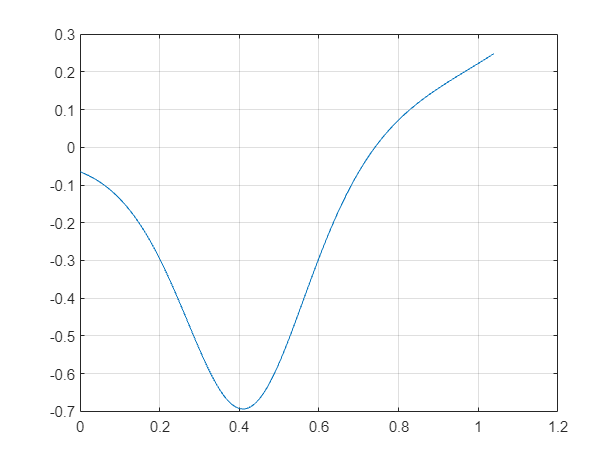

theta_arr = 0:0.01:pi/3;
res = func_dev(theta_arr);
plot(theta_arr, res)
grid on

func = @(h, r) (xi_LoS - xi_NLoS) ./ (1 + b_idx.*exp(-beta_idx.*(180/pi*atan(h/r) - b_idx))) ...
    + 20*log10(r/cos(atan(h/r)) ) + 20*log10(4*pi*f_c/3e8) + xi_NLoS;

func(100, 20)

ans = 79.6356

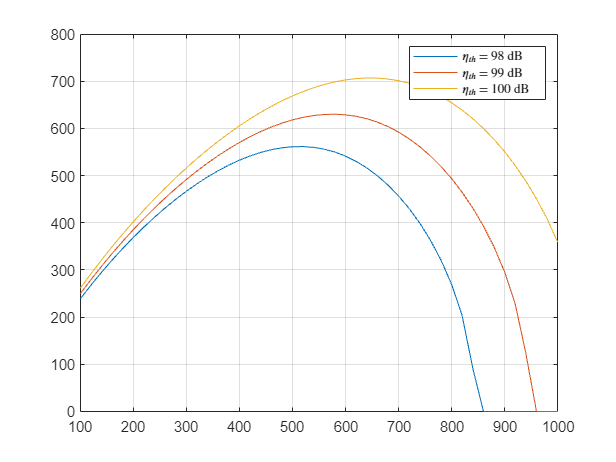

h_arr = 100:20:2000;
eta_th_arr = [98 99 100];
r_arr = zeros(length(eta_th_arr), length(h_arr));

for j = 1:length(eta_th_arr)
    eta_th = eta_th_arr(j);
    for i = 1:length(h_arr) 
    h = h_arr(i);
    func = @(r) (xi_LoS - xi_NLoS) ./ (1 + b_idx.*exp(-beta_idx.*(180/pi*atan(h/r) - b_idx))) ...
    + 20*log10(r/cos(atan(h/r)) ) + 20*log10(4*pi*f_c/3e8) + xi_NLoS;
    
    r_arr(j,i) = bisection(func, 0, 2500, eta_th);
    end
end

plot(h_arr, r_arr)
grid on
xlim([100 1000])
legend('$\eta_{th}$ = 98 dB', '$\eta_{th}$ = 99 dB', '$\eta_{th}$ = 100 dB')
legend('Interpreter', 'latex')

% ylim([100 10])